# Detekcja obiektów na podstawie dopasowania punktów charakterystycznych

Mając zdjęcie interesującego dla nas obiektu oraz fotografię sceny, na której ten obiekt jest widoczny, można na podstawie dopasowania punktów charakterystycznych spróbować odnaleźć dany obiekt na scenie. Warunkiem jest oczywiście to, żeby obiekt posiadał odpowiednią liczbę punktów kluczowych, a więc posiadał wyraźną i w miarę unikalną teksturę. Dobrym przykładem jest lokalizacja książek na podstawie ich okładek.

Przedstawiony kod pochodzi w większości z dokumentacji MATLABa: [https://www.mathworks.com/help/vision/ug/object-detection-in-a-cluttered-scene-using-point-feature-matching.html](https://www.mathworks.com/help/vision/ug/object-detection-in-a-cluttered-scene-using-point-feature-matching.html) 

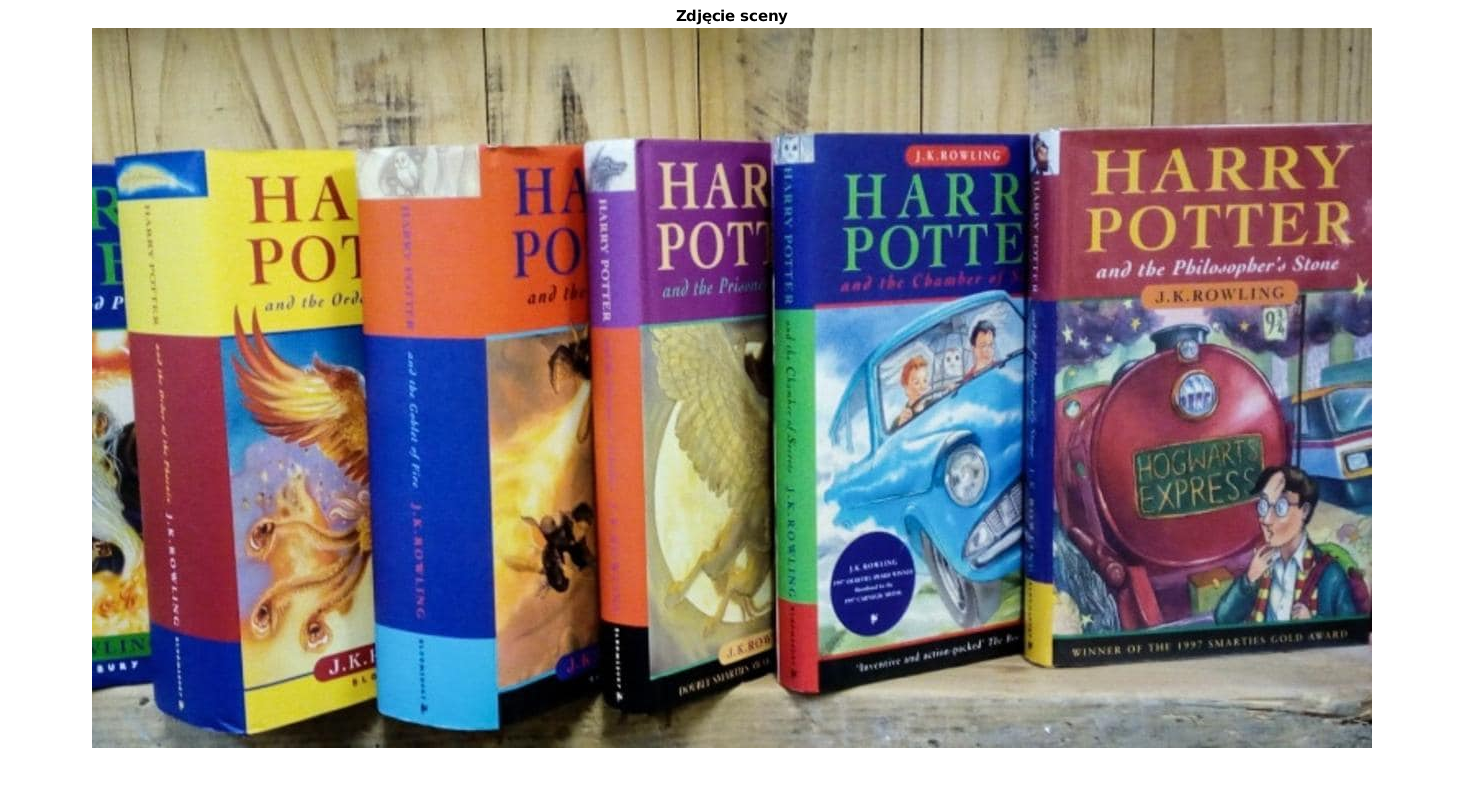

sceneImage = imread('books/books.jpg');
figure;
imshow(sceneImage);
title('Zdjęcie sceny');

W przypadku tego ćwiczenia na zdjęciu widoczne jest kilka książek. Jako model do detekcji wykorzystamy cyfrową wersję okładki jednej z nich. Nie jest ona identyczna jak ta przedstawiona na scenie (nie posiada okrągłej naklejki, ma inny napis na dole), ale główne elementy są takie same.

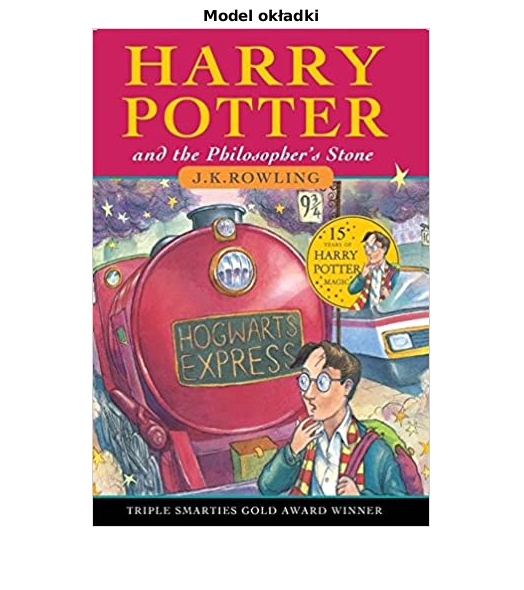

boxImage = imread('books/b1.jpg');
figure;
imshow(boxImage);
title('Model okładki');

## Detekcja punktów modelu oraz sceny

Pierwszym krokiem, podobnie jak przy wyróœnaniu zdjęć, jest detekcja punktów kluczowych w obu obrazach.

boxPoints = detectSURFFeatures(rgb2gray(boxImage), "MetricThreshold", 1000);
scenePoints = detectSURFFeatures(rgb2gray(sceneImage));

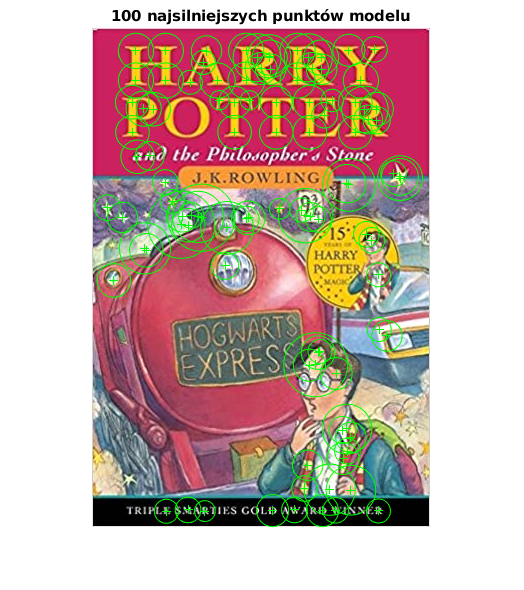

figure;
imshow(boxImage);
title('100 najsilniejszych punktów modelu');
hold on;
plot(selectStrongest(boxPoints, 100));

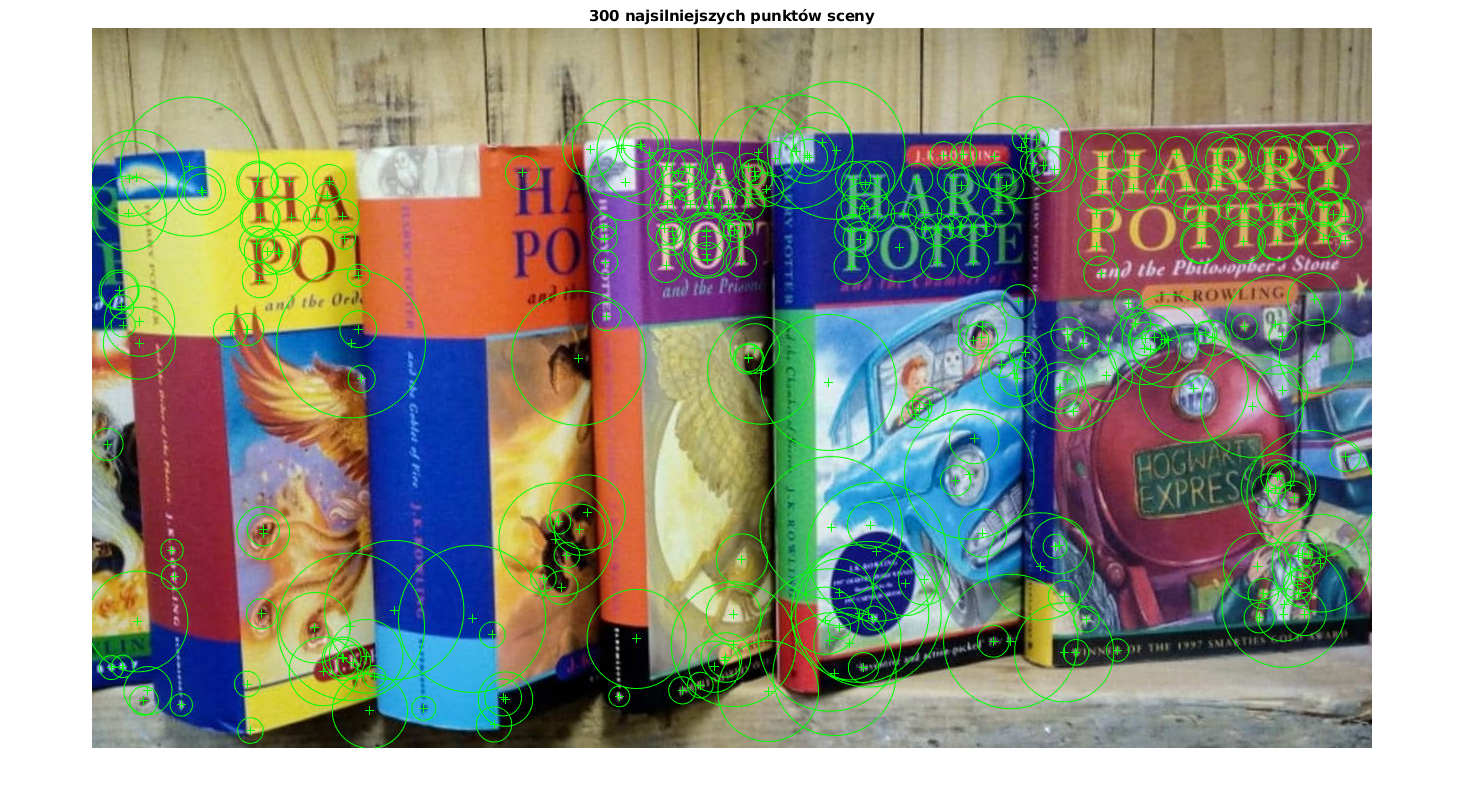

figure;
imshow(sceneImage);
title('300 najsilniejszych punktów sceny');
hold on;
plot(selectStrongest(scenePoints, 300));

Przed dopasowaniem par punktów konieczne jest jeszcze wyznaczenie deskryptorów:

[boxFeatures, boxPoints] = extractFeatures(rgb2gray(boxImage), boxPoints);
[sceneFeatures, scenePoints] = extractFeatures(rgb2gray(sceneImage), scenePoints);

## Dopasowanie punktów modelu do sceny

Po dopasowaniu punktów modelu do punktów sceny widać, podobnie jak przy wyrównaniu obrazów, że niektóre pary nie są poprawne. Największy problem sprawiają obszary tytułu, które na każdej okładce są bardzo podobne.

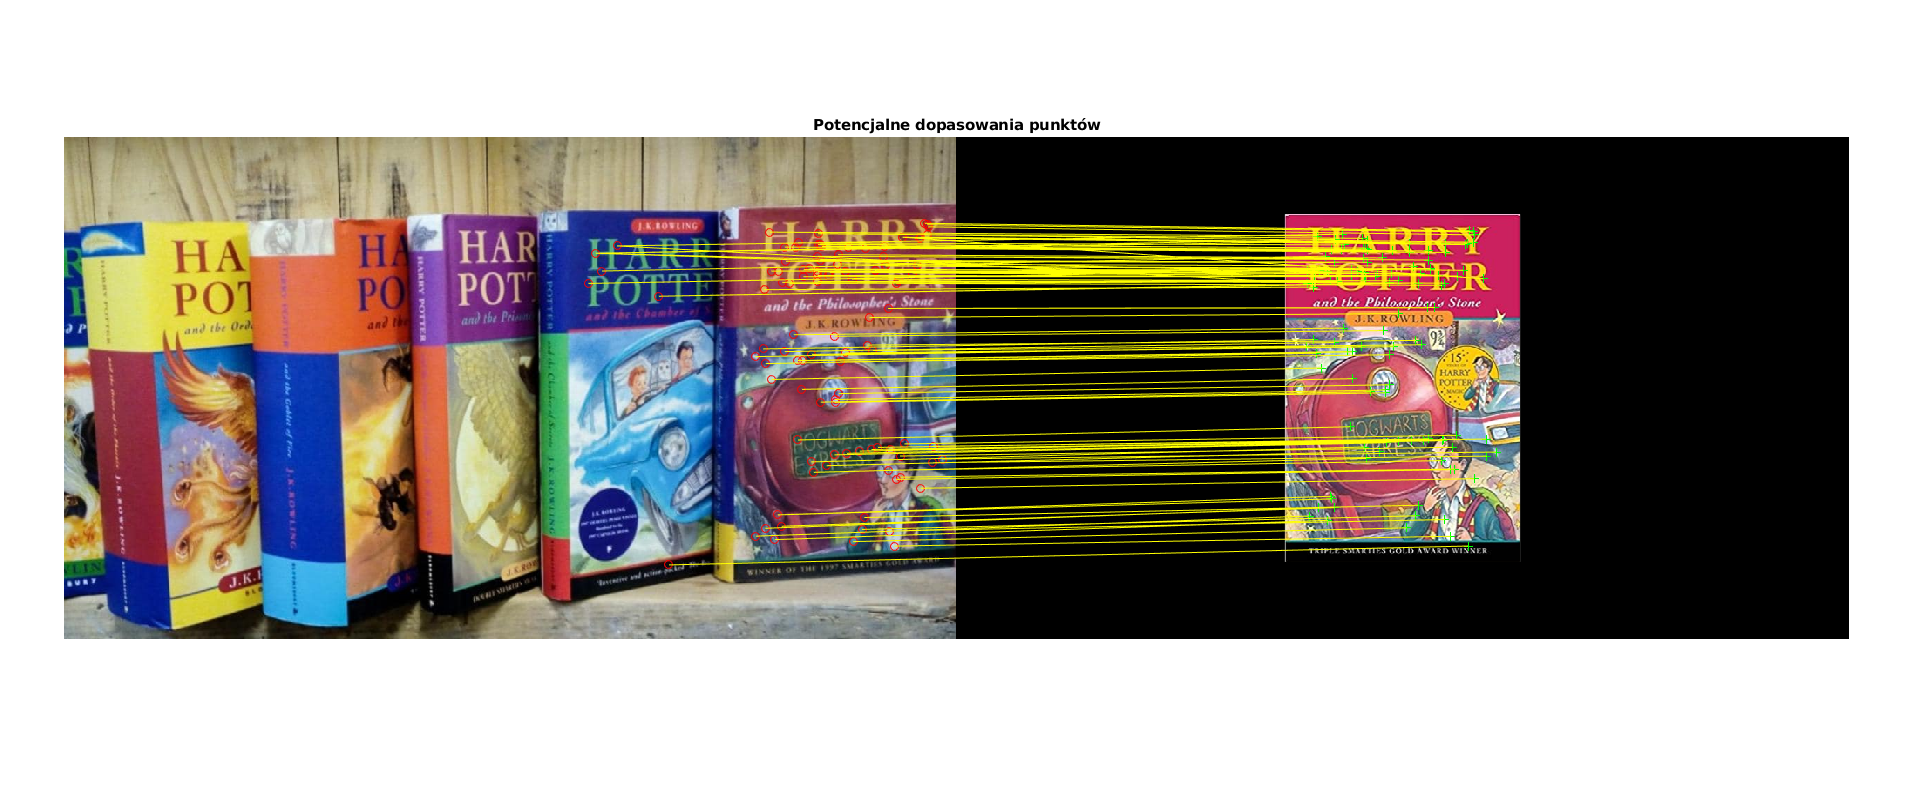

boxPairs = matchFeatures(boxFeatures, sceneFeatures);
matchedBoxPoints = boxPoints(boxPairs(:, 1), :);
matchedScenePoints = scenePoints(boxPairs(:, 2), :);
figure;
showMatchedFeatures(sceneImage, boxImage, matchedScenePoints, matchedBoxPoints, 'montage');
title('Potencjalne dopasowania punktów');

## Filtracja dopasowań i wyznaczenie transformacji

Korzystająć z funkcji bibliotecznej estimateGeometricTransform można wyznaczyć transformację pomiędzy dwoma zbiorami dopasowanych punktów. W przypadku tego ćwiczenia transformacja jest typu "projective", tzn. możliwe są zniekształcenia nie tylko obrotu, przesunięcia i skalowania, ale także perspektywiczne (związane z orientacją obiektu względem kamery). Przyjęty limit dokładności został określony na 1.5 piksela.

[tform, inlierBoxPoints, inlierScenePoints] = estimateGeometricTransform(matchedBoxPoints, matchedScenePoints, 'projective', 'MaxDistance', 1.5);

Oprócz samej transformacji funkcja ta zwraca także listę punktów pasujących do niej. Możemy w ten sposó” zweryfikować, że faktycznie wykryte zostały punkty należące do odpowiedniej książki.

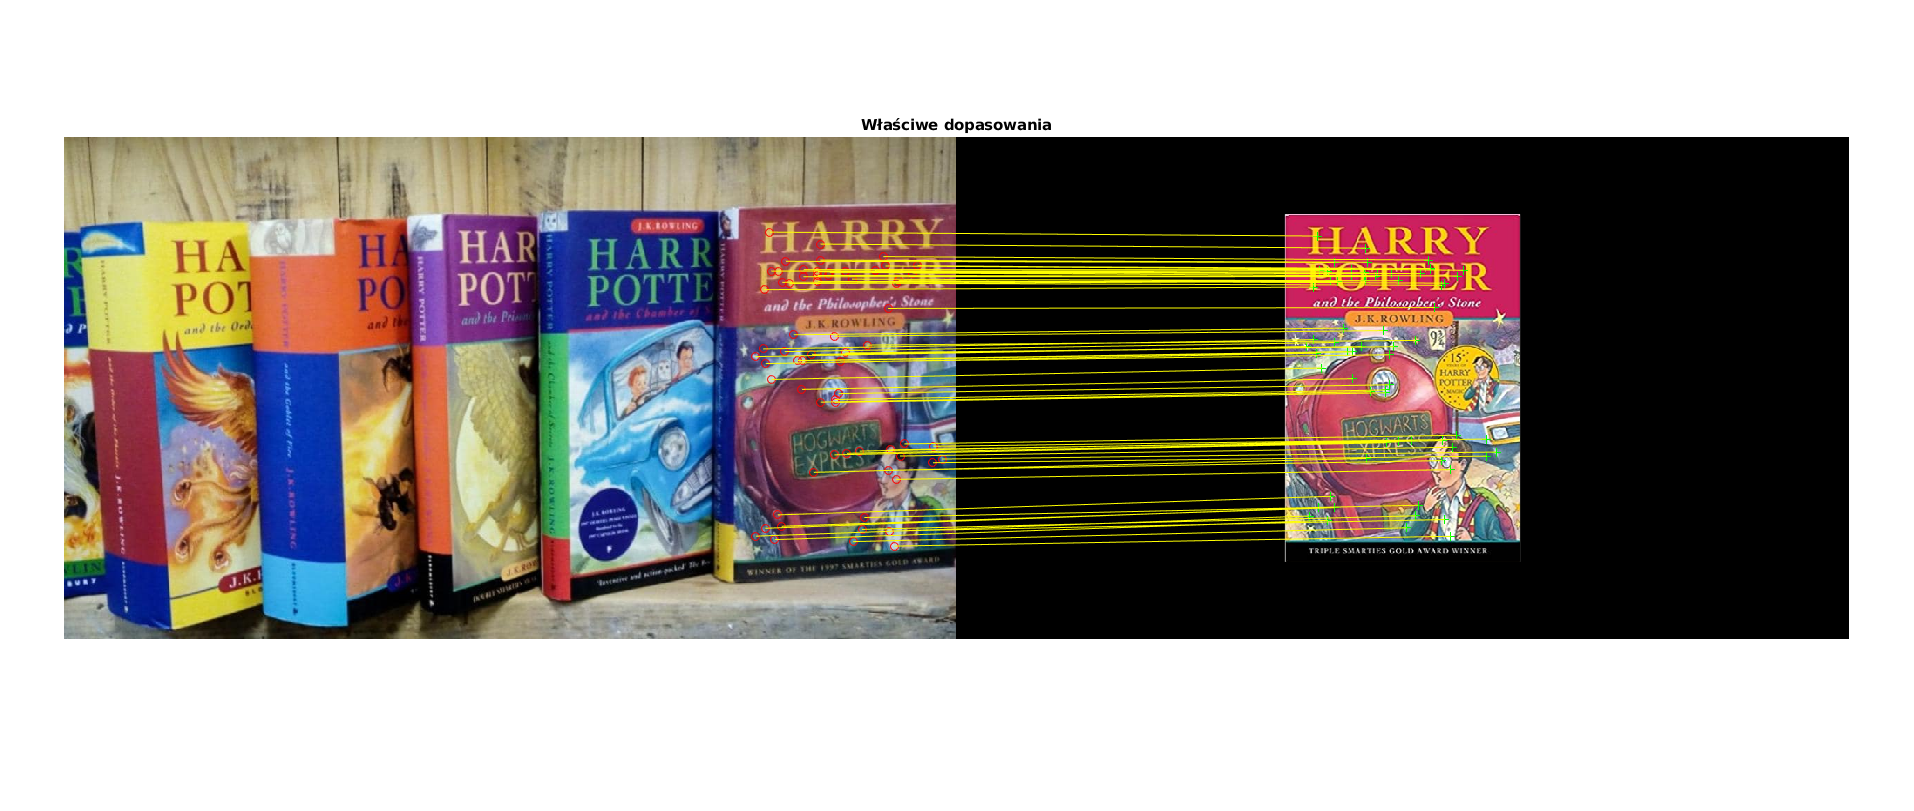

figure;
showMatchedFeatures(sceneImage, boxImage, inlierScenePoints, inlierBoxPoints, 'montage');
title('Właściwe dopasowania');

W ramach wizualizacji można wykorzystać wyznaczoną transformację do przekształcenia prostokąta o wielkości okładki do obrazu sceny. Oryginalne współrzędne odpowiadają wielkości obrazu okładki:

boxPolygon = [1, 1;...                           % top-left
        size(boxImage, 2), 1;...                 % top-right
        size(boxImage, 2), size(boxImage, 1);... % bottom-right
        1, size(boxImage, 1);...                 % bottom-left
        1, 1];                   % top-left again to close the polygon

Przekształcenie współrzędnych przez wyznaczoną transformację:

newBoxPolygon = transformPointsForward(tform, boxPolygon);

Wyświetlenie obrysu zlokalizowanej okładki w obrazie sceny:

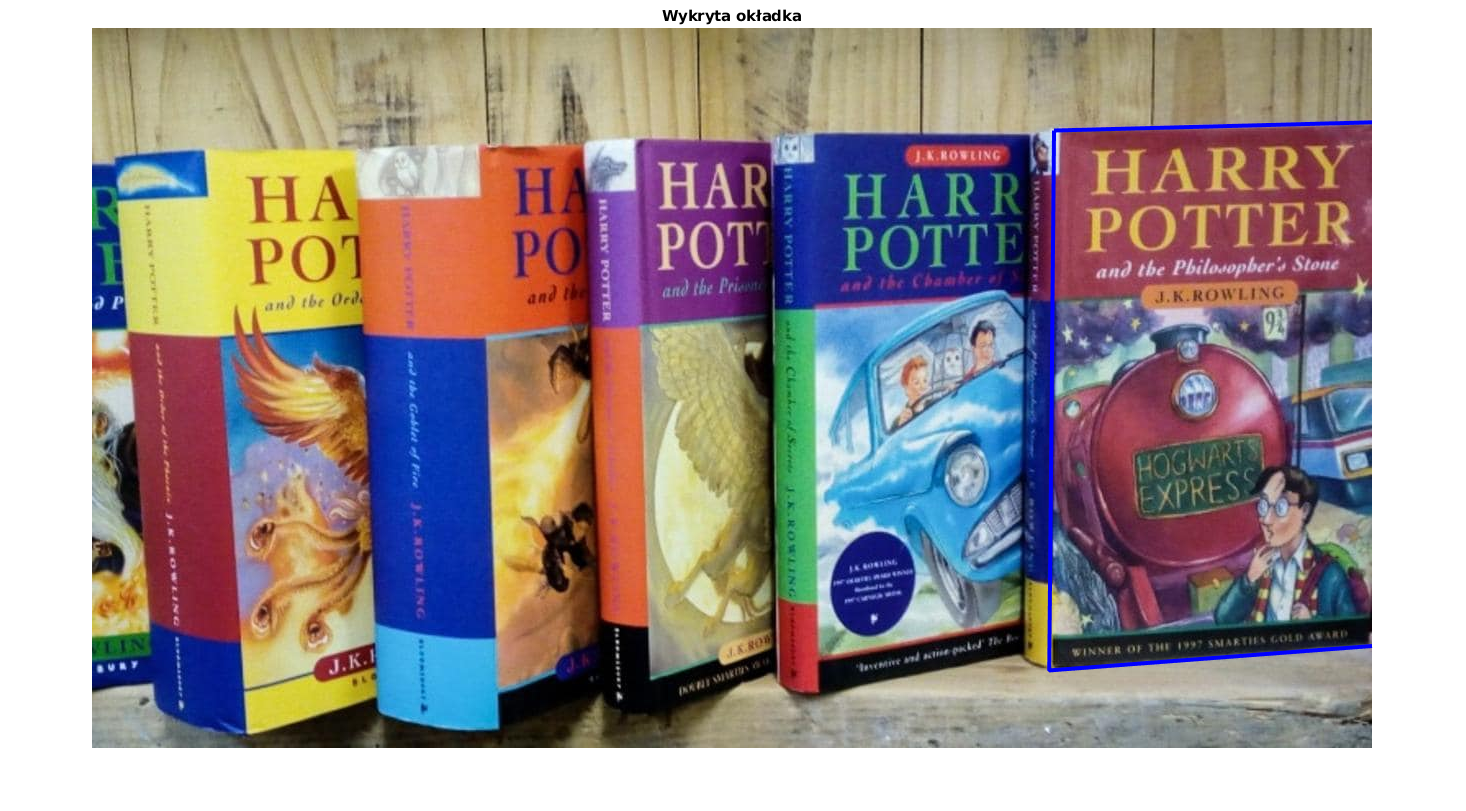

figure;
imshow(sceneImage);
hold on;
line(newBoxPolygon(:, 1), newBoxPolygon(:, 2), 'Color', 'b', 'LineWidth', 3);
title('Wykryta okładka');